# XTD_A3: Symmetry Analysis (Event Boundary & Beta Power)

load('.\XTD_All_PI_PO.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_All_PO_PO.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_DL_PI_PO.mat');

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);
%#ok<*UNRCH>
rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);

objTimeVect = mlb.obsvTimeVect-mlb.obsvTimeVect(1);



## Compile Data

symRatTR = cell(length(fileDirs), mlb.seqLength);
symRatDEC = cell(length(fileDirs), mlb.seqLength);
symRatMN = cell(length(fileDirs), mlb.seqLength);
for ani = 1:length(fileDirs)
    for pos = 1:mlb.seqLength
        tempDs = xtd_D{pos,pos,ani};
        temp_symRatTR = nan(size(tempDs,3),length(mlb.obsvTimeVect));
        temp_symRatDEC = nan(size(tempDs,3),length(mlb.obsvTimeVect));
        temp_symRatMN = nan(size(tempDs,3),length(mlb.obsvTimeVect));
        for trl = 1:size(tempDs,3)
            temp_trialD = tempDs(:,:,trl);
            for t = 10:length(mlb.obsvTimeVect)-10
%                 trVect = temp_trialD(:,t);
%                 decVect = temp_trialD(t,:);
                trVect = smooth(temp_trialD(:,t),'lowess');
                decVect = smooth(temp_trialD(t,:),'lowess');
                mnVect = mean([trVect(:), decVect(:)],2,'omitnan');
                if trVect(t)>0
                    fwdTRlag = find(trVect(t:end)<=0,1,'first');
                    if isempty(fwdTRlag)
                        fwdTRlag = length(trVect)-t;
                    end
                    revTRlag = find(trVect(1:t)<=0,1,'last');
                    if isempty(revTRlag)
                        revTRlag = t;
                    else
                        revTRlag = t-revTRlag;
                    end
                    temp_symRatTR(trl,t) = fwdTRlag - revTRlag;
                end
                if decVect(t)>0
                    fwdDEClag = find(decVect(t:end)<=0,1,'first');
                    if isempty(fwdDEClag)
                        fwdDEClag = length(decVect)-t;
                    end
                    revDEClag = find(decVect(1:t)<=0,1,'last');
                    if isempty(revDEClag)
                        revDEClag = t;
                    else
                        revDEClag = t-revDEClag;
                    end
                    temp_symRatDEC(trl,t) = fwdDEClag - revDEClag;
                end
                if mnVect(t)>0
                    fwdMNlag = find(mnVect(t:end)<=0,1,'first');
                    if isempty(fwdMNlag)
                        fwdMNlag = length(decVect)-t;
                    end
                    revMnLag = find(mnVect(1:t)<=0,1,'last');
                    if isempty(revMnLag)
                        revMnLag = t;
                    else
                        revMnLag = t-revMnLag;
                    end
                    temp_symRatMN(trl,t) = fwdMNlag - revMnLag;
                end
            end
        end
        symRatTR{ani,pos} = temp_symRatTR;
        symRatDEC{ani,pos} = temp_symRatDEC;
        symRatMN{ani,pos} = temp_symRatMN;
    end
end

trialLIGHTlat = [lat_PrtLight{:}];
trialLIGHTlat = trialLIGHTlat(2:end,:)';
% trialLIGHTlat = cell2mat(trialLIGHTlat(:)');
trialPIlat = [lat_TrlStart{:}];
% trialPIlat = cell2mat(trialPIlat(:)');
trialSIGlat = [lat_RwdSig{:}];
% trialSIGlat = cell2mat(trialSIGlat(:)');
trialPOlat = [lat_TrlEnd{:}];
% trialPOlat = cell2mat(trialPOlat(:)');
trialRWDlat = [lat_Rwd{:}];
% trialRWDlat = cell2mat(trialRWDlat(:)');
nxtTrlLats = [lat_NextTrl{:}];
% nxtTrlLats = cell2mat(nxtTrlLats(:)');
prevTrlLats = [lat_PrevTrl{:}];
% prevTrlLats = cell2mat(prevTrlLats(:)');

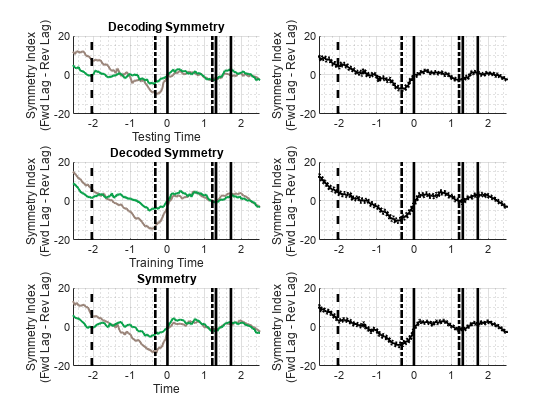


figure;
sps = nan(3,2);
% for p = 1:mlb.seqLength
for p = 2:mlb.seqLength-1
    sps(1) = subplot(3,2,1);
    tempTR = cell2mat(symRatTR(:,p));
    %     tempTR = (tempTR - mean(tempTR(:),'omitnan')) ./ std(tempTR(:),'omitnan');
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempTR,1,0,mlb.PositionColors(p,:));
    sps(2) = subplot(3,2,3);
    tempDEC = cell2mat(symRatDEC(:,p));
    %     tempDEC = (tempDEC - mean(tempDEC(:),'omitnan')) ./ std(tempDEC(:),'omitnan');
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempDEC,1,0,mlb.PositionColors(p,:));
    sps(3) = subplot(3,2,5);
    tempMN = cell2mat(symRatMN(:,p));
    %     tempMN = (tempMN - mean(tempMN(:),'omitnan')) ./ std(tempMN(:),'omitnan');
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempMN,1,0,mlb.PositionColors(p,:));
end
sps(4) = subplot(3,2,2);
% tempTR = cell2mat(symRatTR);
tempTR = cell2mat(reshape(symRatTR(:,2:mlb.seqLength-1),[numel(symRatTR(:,2:mlb.seqLength-1)),1]));
% tempTR = (tempTR - mean(tempTR(:),'omitnan')) ./ std(tempTR(:),'omitnan');
mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempTR,1,0.05,'k');
sps(5) = subplot(3,2,4);
% tempDEC = cell2mat(symRatDEC);
tempDEC = cell2mat(reshape(symRatDEC(:,2:mlb.seqLength-1), [numel(symRatDEC(:,2:mlb.seqLength-1)),1]));
% tempDEC = (tempDEC - mean(tempDEC(:),'omitnan')) ./ std(tempDEC(:),'omitnan');
mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempDEC,1,0.05,'k');
sps(6) = subplot(3,2,6);
% tempMN = cell2mat(symRatMN);
tempMN = cell2mat(reshape(symRatMN(:,2:mlb.seqLength-1), [numel(symRatMN(:,2:mlb.seqLength-1)),1]));
% tempMN = (tempMN - mean(tempMN(:),'omitnan')) ./ std(tempMN(:),'omitnan');
mlb.PlotMeanVarLine(mlb.obsvTimeVect, tempMN,1,0.05,'k');
linkaxes(sps,'xy');

for plt = 1:6
    subplot(3,2,plt);
    if plt==1
        title('Decoding Symmetry');
        xlabel('Testing Time');
    elseif plt==3
        title('Decoded Symmetry');
        xlabel('Training Time');
    elseif plt==5
        title('Symmetry');
        xlabel('Time');
    end
    ylabel([{'Symmetry Index'};{'(Fwd Lag - Rev Lag)'}]);
    plot(repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);

    if strcmp(endTrialBound, 'RWD')
        plot(repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'PO')
        plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'RS')
        plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    end
    plot(repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    grid on;
    grid minor;
end

## LFP Stuff Again because I hate myself

xtd_LFPpower
trialCorr_Power = cell(mlb.seqLength, length(fileDirs));
for ani = 1:length(fileDirs)
    curAni_Power = xtd_LFPpower(:,ani);
    curAni_Sym = symRatTR(ani,:);
    curAni_TrialMask = 
    for pos = 1:mlb.seqLength
        for trl = 1: